%% Test Script for Robot Arm Trajectory Generation
% This script demonstrates the use of the trajectory generation function
% and tests both valid and invalid waypoints

% Clear workspace and close figures
clear;
clf;
close all;
clc;


%% Create Robot Model
robot = RA_CreateRobot();

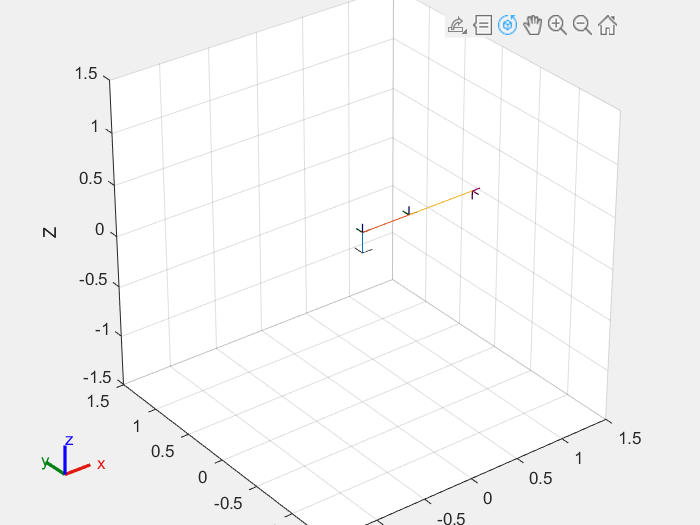


% Display the robot to visualize its structure
figure(1);
show(robot, 'PreservePlot', false);
title('Robot Model');
view(3);


%% Analyze and Visualize Workspace
disp('Generating workspace visualization...');

Generating workspace visualization...


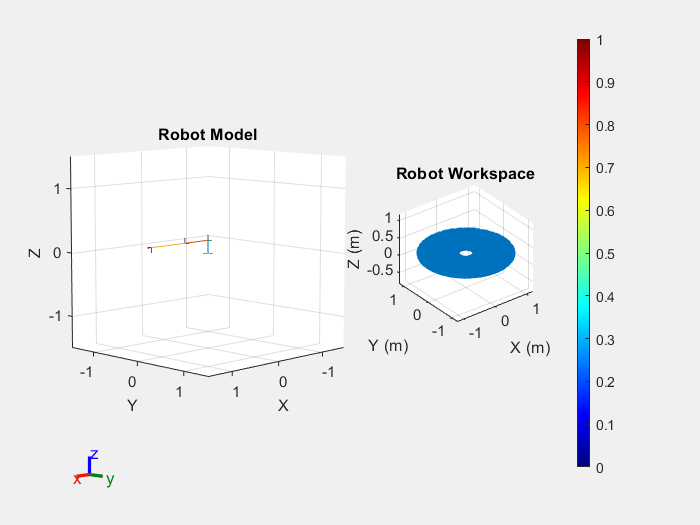

Workspace Statistics:
  Number of points: 8000
  X range: [-1.199, 1.200] m
  Y range: [-1.199, 1.199] m
  Z range: [0.200, 0.200] m
  Bounding box volume: 0.000 m³


[workspacePoints, ~] = RA_VisualizeWorkspace(robot, 8000, true);


%% Example 1: Generate Trajectory with Valid Waypoints
disp('Example 1: Valid waypoints');

Example 1: Valid waypoints



% Define time points for waypoints
tpts = [0, 2, 4, 6];

% Define valid waypoints within the robot's workspace
% These points should be within the robot's reach
valid_wpts = [
    -0.80, -1.1, 1.0,  0.65;  % X coordinates
    1.0, -0.6, 0.80, -0.70;  % Y coordinates
    0.2, 0.2, 0.20,  0.20   % Z coordinates
];

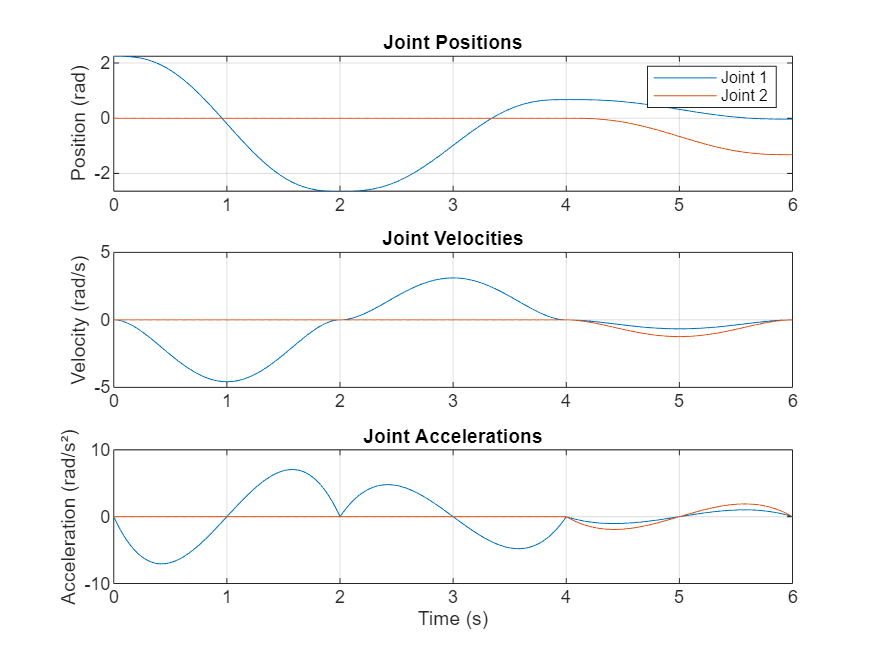

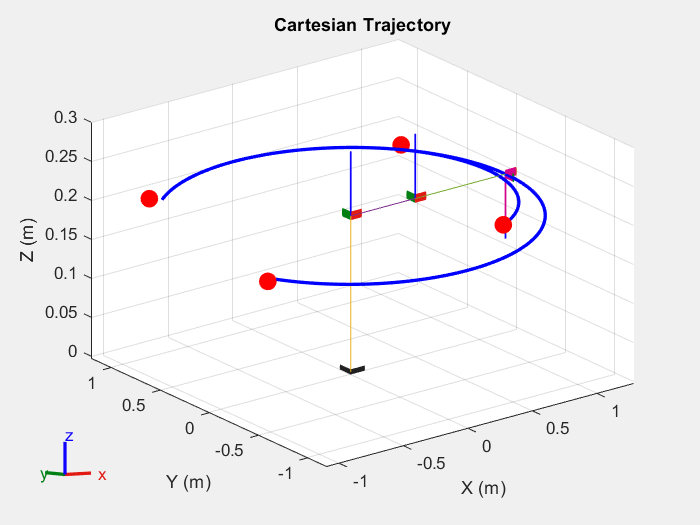

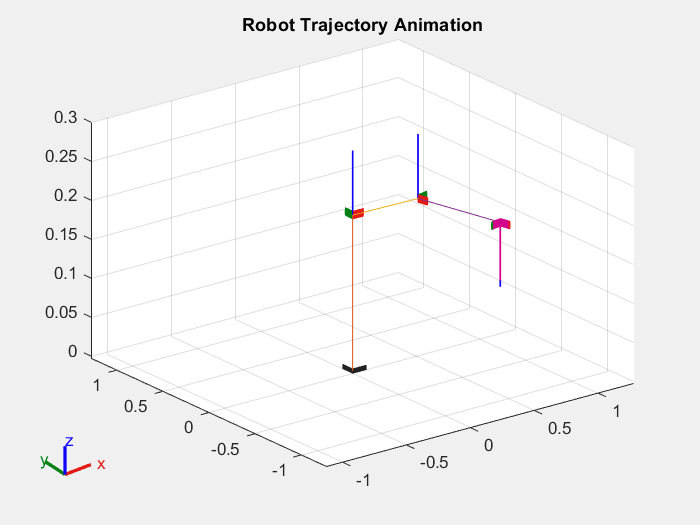

Trajectory generation with valid waypoints succeeded!



try
    % Generate trajectory through valid waypoints
    [q, qd, qdd, tvec] = RA_GenerateJointTrajectory(robot, valid_wpts, tpts);
    
    % Visualize the trajectory
    figure(3);
    
    % Plot joint positions over time
    subplot(3,1,1);
    plot(tvec, q);
    title('Joint Positions');
    ylabel('Position (rad)');
    grid on;
    legend('Joint 1', 'Joint 2');
    
    % Plot joint velocities
    subplot(3,1,2);
    plot(tvec, qd);
    title('Joint Velocities');
    ylabel('Velocity (rad/s)');
    grid on;
    
    % Plot joint accelerations
    subplot(3,1,3);
    plot(tvec, qdd);
    title('Joint Accelerations');
    xlabel('Time (s)');
    ylabel('Acceleration (rad/s²)');
    grid on;
    
    % Visualize the Cartesian path
    figure(4);
    
    % Preallocate arrays for Cartesian trajectory
    numPoints = length(tvec);
    cartesianPath = zeros(3, numPoints);
    
    % Calculate forward kinematics at each time point
    for i = 1:numPoints
        jointAngles = q(:, i);
        transform = RA_ForwardKinematics(robot, jointAngles);
        cartesianPath(:, i) = transform(1:3, 4);
    end
    
    % Plot the 3D trajectory
    plot3(cartesianPath(1,:), cartesianPath(2,:), cartesianPath(3,:), 'b-', 'LineWidth', 2);
    hold on;
    
    % Plot the waypoints
    plot3(valid_wpts(1,:), valid_wpts(2,:), valid_wpts(3,:), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    
    % Add labels and title
    xlabel('X (m)');
    ylabel('Y (m)');
    zlabel('Z (m)');
    title('Cartesian Trajectory');
    grid on;
    
    % Overlay robot at home position
    show(robot, 'PreservePlot', true);
    view(3);
    
    % Create an animation of the robot following the trajectory
    figure(5);
    title('Robot Trajectory Animation');
    hold on;
    grid on;
    view(3);
    
    % Plot at a lower frame rate for visualization
    frameRate = 10; % frames per second
    frameInterval = round(1/(frameRate*0.01)); % interval between frames
    
    % Show initial pose
    h = show(robot, q(:,1), 'PreservePlot', false);
    
    % Only animate a subset of points for better performance
    for i = 1:frameInterval:length(tvec)
        h = show(robot, q(:,i), 'PreservePlot', false);
        drawnow;
        pause(0.05); % small pause for visualization
    end
    
    disp('Trajectory generation with valid waypoints succeeded!');
    
catch ME
    disp('Error in trajectory generation:');
    disp(ME.message);
end

% %% Example 2: Generate Trajectory with Invalid Waypoints
% disp('Example 2: Invalid waypoints');
% 
% % Define waypoints that are outside the robot's workspace
% invalid_wpts = [
%     0.40,  0.45,  0.50,  0.40;  % X coordinates (too far)
%     0.05,  0.10,  0.00, -0.10;  % Y coordinates
%     0.20,  0.15,  0.25,  0.20   % Z coordinates
% ];
% 
% try
%     % Try to generate trajectory through invalid waypoints
%     [q, qd, qdd, tvec] = RA_GenerateJointTrajectory(robot, invalid_wpts, tpts);
% 
%     % If we get here, the error check didn't work
%     warning('Error check failed to detect unreachable waypoints!');
% 
% catch ME
%     % We should get here if the error check is working
%     disp('Expected error with invalid waypoints:');
%     disp(ME.message);
% 
%     % Visualize the invalid waypoints
%     figure(6);
% 
%     % Plot workspace points
%     scatter3(workspacePoints(:,1), workspacePoints(:,2), workspacePoints(:,3), 5, 'b', 'filled');
%     hold on;
% 
%     % Plot invalid waypoints
%     plot3(invalid_wpts(1,:), invalid_wpts(2,:), invalid_wpts(3,:), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
% 
%     % Add labels and title
%     xlabel('X (m)');
%     ylabel('Y (m)');
%     zlabel('Z (m)');
%     title('Invalid Waypoints Outside Workspace');
%     grid on;
% 
%     % Overlay robot at home position
%     show(robot, 'PreservePlot', true);
%     view(3);
% end

%% Example 3: Mixed Valid and Invalid Waypoints
disp('Example 3: Mixed valid and invalid waypoints');

Example 3: Mixed valid and invalid waypoints



% Define a mix of valid and invalid waypoints
mixed_wpts = [
    0.10,  0.50,  0.15,  0.05;  % X coordinates (second point is too far)
    0.05,  0.10,  0.00, -0.10;  % Y coordinates
    0.20,  0.15,  0.25,  0.20   % Z coordinates
];

try
    % Try to generate trajectory through mixed waypoints
    [q, qd, qdd, tvec] = RA_GenerateJointTrajectory(robot, mixed_wpts, tpts);
    
    % If we get here, the error check didn't work
    warning('Error check failed to detect unreachable waypoints!');
    
catch ME
    % We should get here if the error check is working
    disp('Expected error with mixed waypoints:');
    disp(ME.message);
    
    % Visualize the mixed waypoints
    figure(7);
    
    % Plot workspace points
    scatter3(workspacePoints(:,1), workspacePoints(:,2), workspacePoints(:,3), 5, 'b', 'filled');
    hold on;
    
    % Plot mixed waypoints with different colors
    for i = 1:size(mixed_wpts, 2)
        if i == 2  % This is our invalid point
            color = 'r';  % Red for invalid
        else
            color = 'g';  % Green for valid
        end
        plot3(mixed_wpts(1,i), mixed_wpts(2,i), mixed_wpts(3,i), 'o', 'Color', color, ...
              'MarkerSize', 10, 'MarkerFaceColor', color);
    end
    
    % Add labels and title
    xlabel('X (m)');
    ylabel('Y (m)');
    zlabel('Z (m)');
    title('Mixed Valid and Invalid Waypoints');
    grid on;
    legend('Workspace', 'Invalid Point', 'Valid Point');
    
    % Overlay robot at home position
    show(robot, 'PreservePlot', true);
    view(3);
end